# **Image processing**

## 2.1) Filtering Images with Kernels

## Sharpen

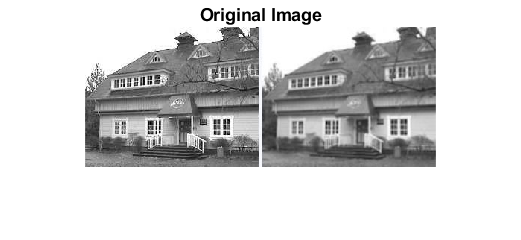

clear
image=imread("house.jpg");
imshow(image);
title("Original Image")

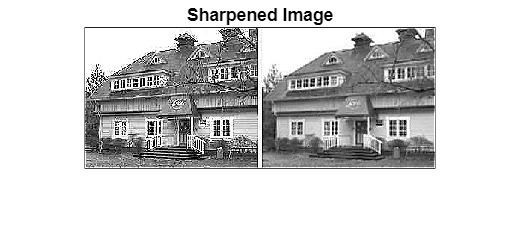

image=rgb2gray(image);
sharpen=[0,-1,0;-1,5,-1;0,-1,0];
im_sharpened=conv2(sharpen,image);
imshow(abs(uint8(im_sharpened)));
title("Sharpened Image")

## Blur

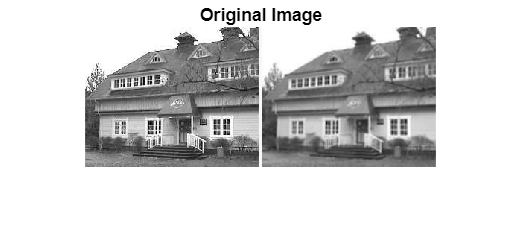

imshow(image);
title("Original Image")

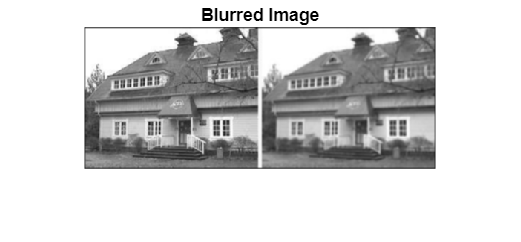

blur=[0.0625,0.125,0.0625;0.125,0.25,0.125;0.0625,0.125,0.0625];
im_blurred=conv2(blur,image);
imshow(uint8(im_blurred));
title("Blurred Image")

## Outline

imshow(image);
title("Original Image")

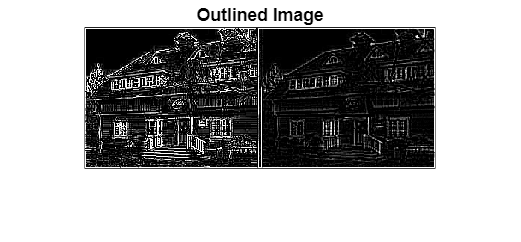

outline=[-1,-1,-1;-1,8,-1;-1,-1,-1];
im_outlined=conv2(outline,image);
imshow(abs(uint8((im_outlined))));
title("Outlined Image")

## Gauss

imshow(image);
title("Original Image")

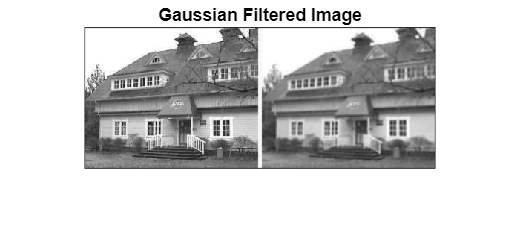

gauss=[0.0113,0.0838,0.0113;0.0838,0.6193,0.0838;0.0113,0.0838,0.0113];
im_gauss=conv2(gauss,image);
imshow(uint8(im_gauss));
title("Gaussian Filtered Image")

## Avg Moving

imshow(image);
title("Original Image")

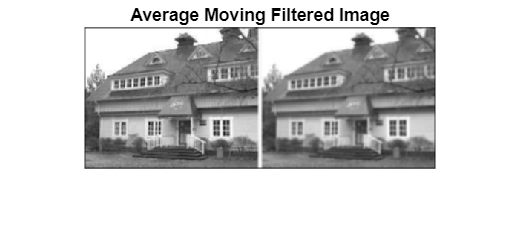

avg_moving=[0.1111,0.1111,0.1111;0.1111,0.1111,0.1111;0.1111,0.1111,0.1111];
im_avg_moving=conv2(avg_moving,image);
imshow(uint8(im_avg_moving));
title("Average Moving Filtered Image")

## Line H

imshow(image);
title("Original Image")

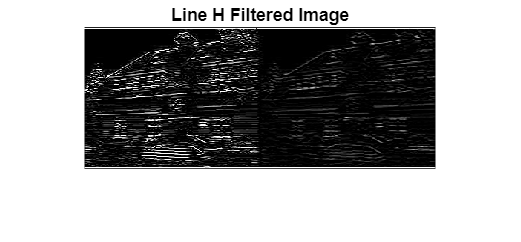

line_H=[-1,-1,-1;2,2,2;-1,-1,-1];
im_line_H=conv2(line_H,image);
imshow(abs(uint8(im_line_H)));
title("Line H Filtered Image")

## Line V

imshow(image);
title("Original Image")

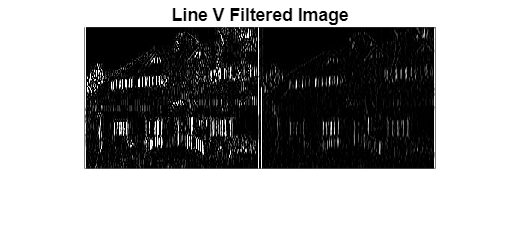

line_V=[-1,2,-1;-1,2,-1;-1,2,-1];
im_line_V=conv2(line_V,image);
imshow(abs(uint8(im_line_V)));
title("Line V Filtered Image")

## Identity

imshow(image);
title("Original Image")

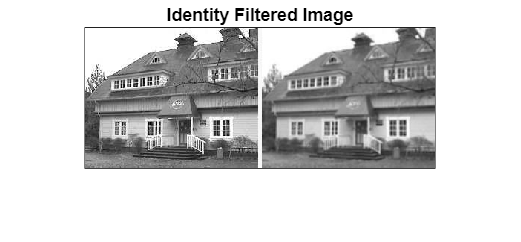

identity=[0,0,0;0,1,0;0,0,0];
im_identity=conv2(identity,image);
imshow(uint8(im_identity));
title("Identity Filtered Image")

## 2.2) Resizing Images

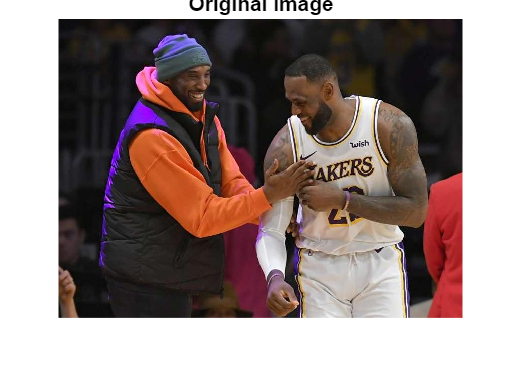

image2=imread("kobe.jpeg");
imshow(image2);
title("Original Image")

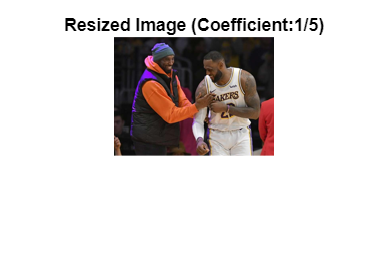

Resized_image_down=imresize(image2,1/5);
imshow(Resized_image_down);
title("Resized Image (Coefficient:1/5)")

imshow(image2);
title("Original Image")

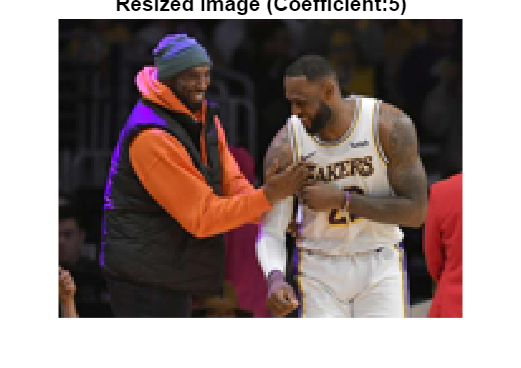

Resized_image_up=imresize(Resized_image_down,5,'nearest');
imshow(Resized_image_up);
title("Resized Image (Coefficient:5)")

## Improving the Image by Gaussian and Avg-Moving Kernels

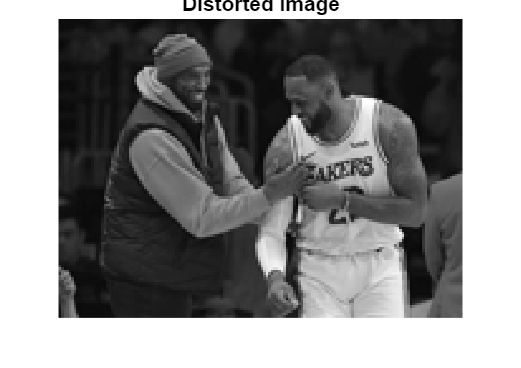

Distorted_image=rgb2gray(Resized_image_up);
imshow(Distorted_image);
title("Distorted Image")

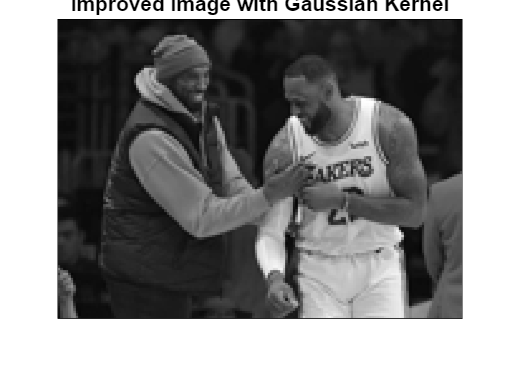

improved_image_gauss=conv2(gauss,Distorted_image);
improved_image_avg=conv2(avg_moving,Distorted_image);
imshow(uint8(improved_image_gauss));
title("Improved Image with Gaussian Kernel")

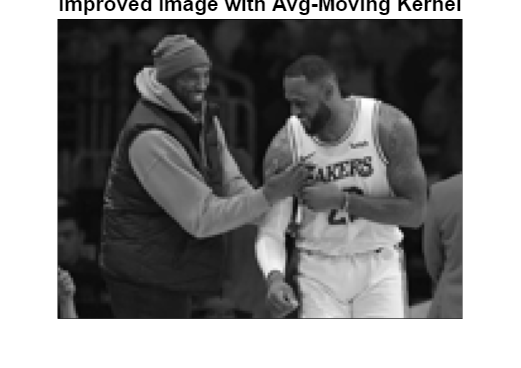

imshow(uint8(improved_image_avg));
title("Improved Image with Avg-Moving Kernel")

## 2.3) Bonus+

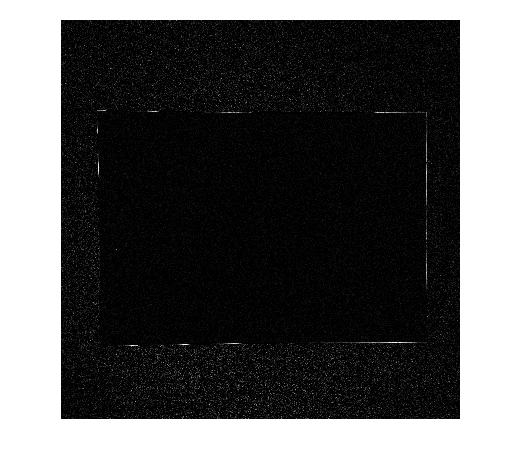

image3=imread("page.jpg");
image3=rgb2gray(image3);
im3_line_H=conv2(line_H,image3);
im3_line_V=conv2(line_V,image3);
im3_line_HV=im3_line_H+im3_line_V;
imshow(abs(uint8(im3_line_HV)));

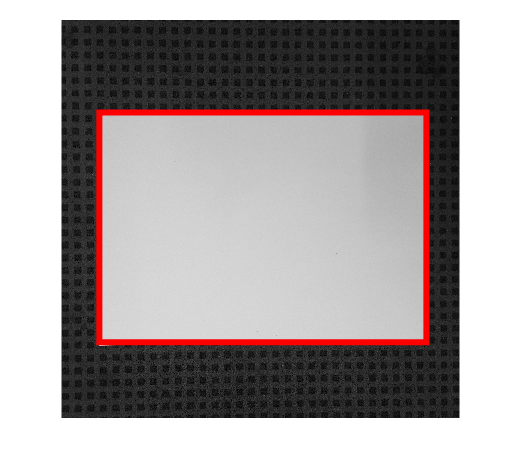

Horizontal=sum(abs(im3_line_H'));
H_sort=sort(Horizontal(20:length(Horizontal)-20));
H1_point=find(Horizontal==H_sort(length(H_sort)));
H2_point=find(Horizontal==H_sort(length(H_sort)-1));
Vertical=sum(abs(im3_line_V));
V_sort=sort(Vertical(20:length(Vertical)-20));
V1_point=find(Vertical==V_sort(length(V_sort)));
V2_point=find(Vertical==V_sort(length(V_sort)-1));
imshow(image3);
rectangle("Position",[V1_point,H1_point,V2_point-V1_point,H2_point-H1_point],"EdgeColor",'r',"LineWidth",3);